# Optimization Homework

Kathryn Atherton

ABE 55800

March 4, 2019

## Problem 9.1 (PTW): 

 A multiple-effect evaporator is to be used for evaporating 200,000 kg of water per day from a salt solution. The total initial cost for the first effect is $18,000, and each additional effect costs $15,000. The service life of the evaporator is estimated to be 10 years, and the salvage or scrap value at the end of the life period may be assumed to be zero. The straight-line depreciation method is used. Fixed charges minus depreciation are 15 percent yearly, based on the first cost of the equipment. Steam costs $0.0033/kg. Annual maintenance charges are 5 percent of the initial equipment cost. All other costs are independent of the number of effects. The unit will operate 300 days/year. If the kilograms of water evaporated per kilogram of steam equals 0.85(number of effects), determine the optimum number of effects for minimum annual cost. 

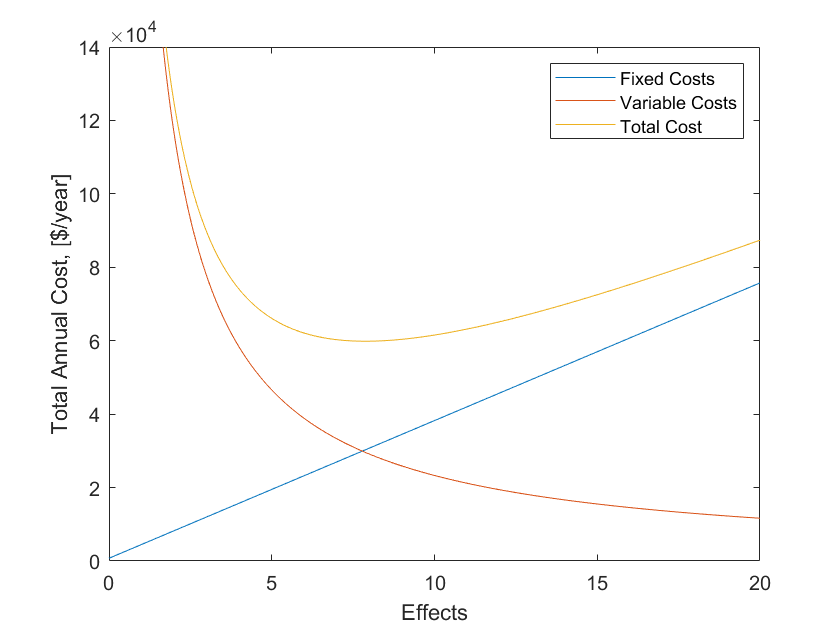

evap = 200000; % [kg water/day]
invest_1 = 18000;  % [$]
invest_2ormore = 15000; % [$]
n = 10; % [years]
scrap_value = 0; % [$]
fixed_charges = 0.15; % [% of initial equipment costs]
steam = 0.0033; % [$/kg]
maintenance = 0.05; % [% of initial equipment costs]
days = 300; % [days/year]
evap_rate = 0.85; % [kg water/kg steam/effect]

syms x % effects
initial_cost = invest_1 + invest_2ormore * (x - 1);
dep = initial_cost / n; 
fixed_costs = fixed_charges * initial_cost + dep + fixed_charges * maintenance;
water_evaporated = evap_rate * x; 
steam_cost = steam / water_evaporated * evap * days;
total_cost = fixed_costs + steam_cost;
ezplot(fixed_costs,[0,20])
hold on
ezplot(steam_cost, [0,20])
ezplot(total_cost, [0,20])
hold off
ylim([0,14e4])
ylabel('Total Annual Cost, [$/year]')
xlabel('Effects')
legend('Fixed Costs', 'Variable Costs', 'Total Cost')
title(' ')

opt_effects = newton_raphson(diff(total_cost), 5, 0.001)

opt_effects = 7.8815

x = 7;
double(subs(total_cost))

ans = 6.0277e+04

x = 8;
double(subs(total_cost))

ans = 5.9868e+04

**The optimum number of effects is 8.**

## Problem 9.2 (PTW):

Determine the optimum economic thickness of insulation that should be used under the following conditions: Saturated steam is being passed continuously through a steel pipe with an outside diameter of 0.273 m. The temperature of the steam is 480 K, and the steam is valued at $0.004/kg. The pipe is to be inuslated with a material that has a thermal conductivity of 5.2 x 10^-2 W/m.k. The cost of the installed inuslation per meter of pipe length is $180lt, where lt is the thickness of the insulation in meters. Annual fixed charges including maintenance amount to 20 percent of the initial installed cost. The total length of the pipe is 300 m, and the average temperature of the surroundings may be taken as 295 K. Heat-transfer resistances due to the steam film, scale, and pipe wall are negligible. The air-film coefficient at the outside of the insulation may be assumed constant at 11.4 W/m^2.K, for all insulation thickness. 

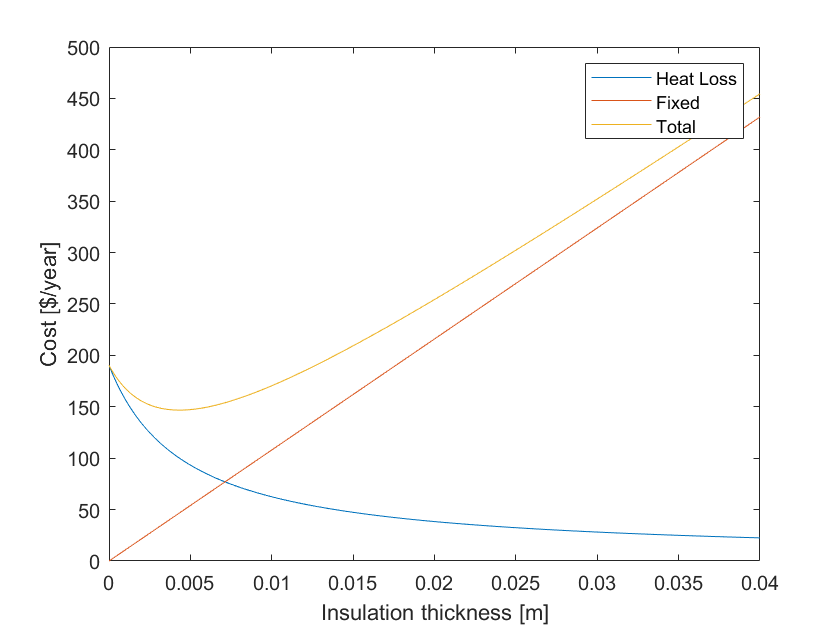

diam_out = 0.273; % [m]
T_steam = 480; % [K]
cost_steam = 0.004; % [$/kg]
k = 5.2e-2; % [W/m.K]
cost_insulation = 180; % [$/m, thickness]
fixed_charges = 0.2; % [% of initial installed cost]
l = 300; % [m]
T_surroundings = 295; % [K]
coeff_a_f = 11.4; % [W/m^2.K]

syms x % Insulation thickness
A_fixed = fixed_charges * (cost_insulation * x * l);
r1 = diam_out / 2; 
r2 = r1 + x; 
Q = 2 * pi * l * (T_steam - T_surroundings) / (1 / (coeff_a_f * r2) + (log(r2/r1)/k));
A_heatloss = (Q / coeff_a_f) * (cost_steam);
A_total = A_fixed + A_heatloss;
ezplot(A_heatloss, [0, 0.04]);
hold on
ezplot(A_fixed, [0, 0.04]);
hold on
ezplot(A_total, [0, 0.04]);
hold off
ylabel('Cost [$/year]')
xlabel('Insulation thickness [m]')
title(' ')
legend('Heat Loss', 'Fixed', 'Total')
ylim([0,500])

optimize = A_heatloss - A_fixed; 
opt_it = newton_raphson(optimize, 0.01, 0.001)

opt_it = 0.0071

**Answer: The optimal thickness of the insulation is 0.0071 m.**

## Problem 9-4 (PTW):

Derive an expression for the optimum economic thickness of inuslation to put on a flat surface if the annual fixed charges per squre meter of insulation are directly proportional to the thickness, 

(a) neglecting the air film and 


$$q=\frac{k\Delta T}{\delta_{\mathrm{ins}} }$$


Annual Heat cost = $q*c_h *t_{\mathrm{op}}$

Annual Fixed Cost = ${\mathrm{FC}}_{a,\mathrm{ins}} *\delta_{\mathrm{ins}}$

Annual Total Cost= $\frac{k\Delta Tc_h t_{\mathrm{op}} }{\delta_{\mathrm{ins}} }+{\mathrm{FC}}_{a,\mathrm{ins}} \delta_{\mathrm{ins}}$

To optimize, find the derivitive and set equal to 0


$$0=-\frac{k\Delta Tc_h t_{\mathrm{op}} }{\delta_{\mathrm{ins}} }+{\mathrm{FC}}_{a,\mathrm{ins}}$$



$$\delta_{\mathrm{opt}} =\sqrt{\frac{k\Delta Tc_h t_{\mathrm{op}} }{{\mathrm{FC}}_{a,\mathrm{ins}} }}$$


where c_h = heat cost

t_op = operation time per year in hours

FC_a,ins = fixed cost of insulation, annualized

(b) including the air film. The air-film coefficient of heat transfer may be assumed to be constant for all insulation thicknesses.


$$\begin{array}{l}
q=U\Delta T\\
\frac{1}{U}=\frac{\delta_{\mathrm{ins}} }{k}+\frac{1}{h_{\mathrm{air}} }\\
U=\frac{kh_{\mathrm{air}} }{k+\delta_{\mathrm{ins}} +h_{\mathrm{air}} }\\
q=\frac{kh_{\mathrm{air}} \Delta T}{k+\delta_{\mathrm{ins}} +h_{\mathrm{air}} }
\end{array}$$


Annual Heat Cost = $qc_h t_{\mathrm{op}} =$$\frac{kh_{\textrm{air}} \Delta Tc_h t_{\mathrm{op}} }{k+\delta_{\textrm{ins}} h_{\textrm{air}} }$

Annual Fixed Cost = ${\mathrm{FC}}_{a,\mathrm{ins}} \delta_{\mathrm{ins}}$

Annual Total Cost = $\frac{kh_{\textrm{air}} \Delta Tc_h t_{\mathrm{op}} }{k+\delta_{\textrm{ins}} h_{\textrm{air}} }+$${\textrm{FC}}_{a,\textrm{ins}} \delta_{\textrm{ins}}$

To optimize, take derivitive and set equal to 0


$$0=-$$

$$\frac{k{h_{\textrm{air}} }^2 \Delta Tc_h t_{\textrm{op}} }{{\left(k+\delta_{\textrm{ins}} h_{\textrm{air}} \right)}^2 }+$$

$${\textrm{FC}}_{a,\textrm{ins}}$$


${\left(k+\delta_{\textrm{ins}} h_{\textrm{air}} \right)}^2$=$\frac{k{h_{\textrm{air}} }^2 \Delta Tc_h t_{\textrm{op}} }{{\textrm{FC}}_{a,\textrm{ins}} }$

$k+\delta_{\textrm{ins}} h_{\textrm{air}}$=$h_{\textrm{air}} \sqrt{\frac{k\Delta Tc_h t_{\textrm{op}} }{{\textrm{FC}}_{a,\textrm{ins}} }}$


$$\delta_{\textrm{opt}} =\sqrt{\frac{k\Delta Tc_h t_{\textrm{op}} }{{\textrm{FC}}_{a,\textrm{ins}} }}-\frac{k}{h_{\mathrm{air}} }$$


## Problem 9-5 (PTW):

A continuous evaporator is operated with a given feed material under conditions in which the concentration of the product remains constant. The feed rate at the start of a cycle after the tubes have been cleaned has been found to be 5000 kg/h. After 48 h of continuous operation, tests have shown that the feed rate decreases to 2500 kg/h. The reduction in capacity is due to true scale formation. If the downtime per cycle for emptying, cleaning, and recharging is 6 h, how long should the evaporator be operated between cleanings in order to obtian the maximum amount of product per 30 days?

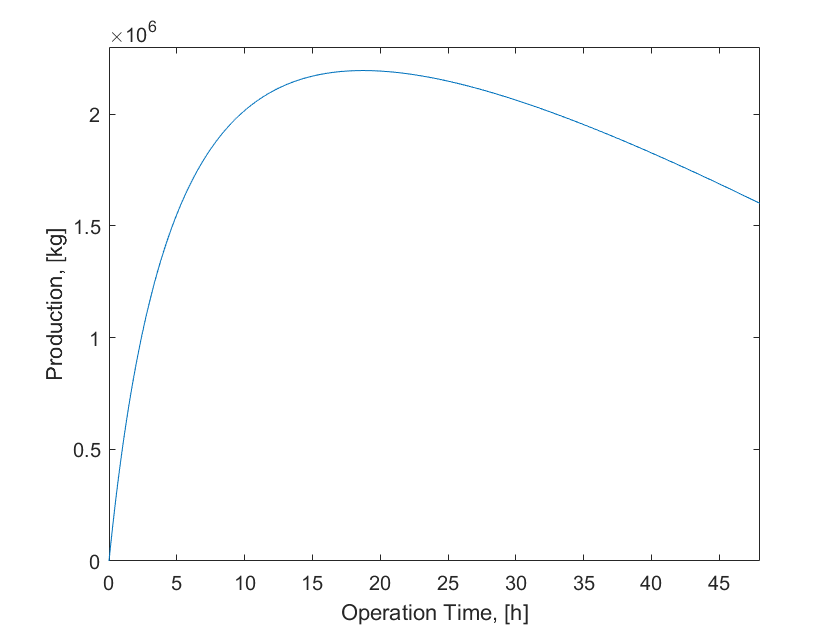

feed = 5000; % [kg/h]
t = 48; % [h]
feed_t = 2500; % [kg/h]
t_e_c_r = 6; % [h]
days = 30; % [days]

time_total = days * 24; 
k = (feed - feed_t) / t; 
syms x % time
N = time_total / (x + 6); % cycles
P = (feed - k * x) * x * N; 
ezplot(P, [0, 48])
ylim([0,2.3e6])
xlabel('Operation Time, [h]')
ylabel('Production, [kg]')
title(' ')

opt_time = newton_raphson(diff(P), 15, 0.001)

opt_time = 18.7386

**Answer: The optimum processing time is 18.7386 hours.**

## Problem 9-6 (PTW):

A solvent extraction operation is carried out continuously in a plate column with gravity flow. The unit is operated 24 h/day. A feed rate of 40 m^3/day must be handled 300 days/year. The allowable velocity per square meter of cross-sectional tower area is 12.2 m^3 of combined solvent and charge per hour. The annual fixed costs for the installed equipment can be predicted from the following equation:

Cf = 8800Fsf^2 - 5100 Fsf + 110,000 $/year

where Fsf is the cubic meters of solvent per cubic meter of feed. Operating and other variable costs depend on the amount of solvent that must be recovered, and these costs are $1.41 for each cubic meter of solvent passing through the tower. What tower diameter should be used for optimum conditions of minimum total cost per year?

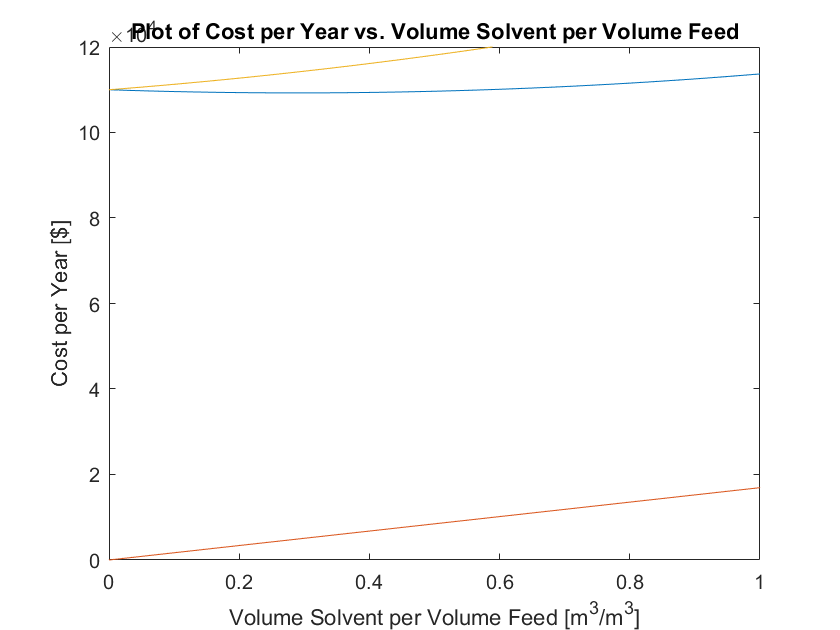

h = 24; % [hours/day]
feed = 40; % [m^3/day]
days = 300; % [days/year]
vel = 12.2; % [m^3/h / m^2 tower area]
costs = 1.41; % [m^3 solvent]
syms x
cf = 8800 * x ^ 2 - 5100 * x + 110000; % fixed costs yearly
cv = costs * x * feed * days; % variable costs yearly
c = cf + cv; % total costs yearly
ezplot(cf)
hold on
ezplot(cv)
hold on
ezplot(c)
title('Plot of Cost per Year vs. Volume Solvent per Volume Feed')
xlabel('Volume Solvent per Volume Feed [m^3/m^3]')
ylabel('Cost per Year [$]')
xlim([0,1])
ylim([0,12e4])
hold off

When including variable costs, the minimum cost per year is when there is no solvent in the feed. This is unfeasible. As such, we will use the minimum of the fixed costs to find the optimum volume of solvent in the feed. 

min_cost_fsf = newton_raphson(diff(cf), 0, 0.001)

min_cost_fsf = 0.2898

**Answer: **The optimum diameter is 0.42 m and the optimum volume of solvent in the feed is 0.29 m^3 per m^3 of feed. 

## Problem 9-9 (PTW): 

A continuous evaporator is being used to concentrate a scale-forming solution of sodium sulfate in water. The overall coefficient of heat transfer decreases according to 

U^-2 = 6.88 x 10^-5 * theta_b + 0.186

where U = overall coefficient of heat transfer, (kJ/s)/(m^2-K) and theta_b = time in operation, s. The only factor which affects the overall coefficient is the scale formation. The liquid enters the evaporator at the boiling point, and the temperature and heat of vaporization are constant. At the operating conditions, 2300 kJ is required to vaporize 1 kg of water, the heat-transfer area is 37 m^2. and the temperature-difference driving force is 40 C . The time required to shut down, clean, and get back on stream is 4 h for each shutdown, and the total cost for this cleaning operation is $100 per cycle. The labor costs during operation of the evaporator are $20 per hour. 

clear;
energy = 2300; % [kJ/kg water]
area = 37; % [m^2]
delta_T = 40; % [C or K]
time = 4; % [hours]
cleaning_cost = 100; % [$/cycle] 
labor_cost = 20; % [$/h]
a = 6.88e-5;
c = 0.186;

Determine the total time per cycle for minimum total cost under the following conditions:

a. An overall average of 30,000 kg of water per 24-h day must be evaporated during each 30-day period.

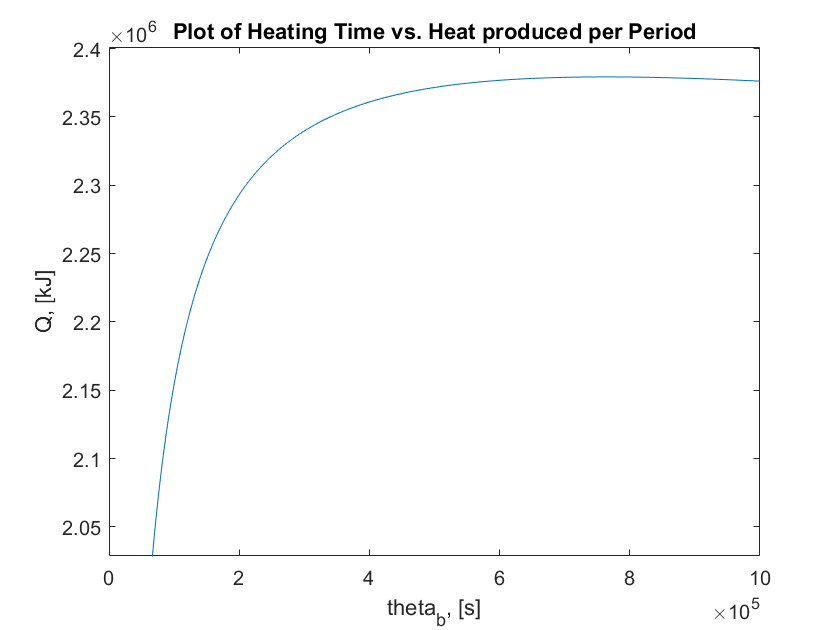

mass = 30000; % kg water/day 
period = 30; % 24 hour days

energy_period = mass * energy * period; % [kJ/period]

syms x % theta_b
Q_cycle = 2 * area * delta_T / a * (((a * (x / 3600) + c) ^ (1/2)) - (c ^ (1/2))); % [kJ/cycle], Equation 9-56
Q_period = Q_cycle * period * 24 / (x / 3600 + 4);  % [kJ/period], Equation 9-57

ezplot(Q_period, [0,10e5])
title('Plot of Heating Time vs. Heat produced per Period')
xlabel('theta_b, [s]')
ylabel('Q, [kJ]')
hold off

opt_theta_b = newton_raphson(diff(Q_period), 5e5, 0.001) % [s]

opt_theta_b = 7.6171e+05

The optimum cycle time is 7.6e5 s. This permits the maximum amount of heat transfer per cycle. 

Q_cycle = double(subs(Q_cycle, x, opt_theta_b)) % [kJ/cycle]

Q_cycle = 7.1241e+05

cycles = energy_period / Q_cycle

cycles = 2.9056e+03

cost = cleaning_cost + labor_cost * (opt_theta_b / 3600 + 4) * cycles

cost = 1.2528e+07

**Answer: The optimum cost is $12,528,000 per 30 day period. **

b. An overall average of 37,000 kg of water per 24-h day must be evaporated during each 30-day period.

mass = 37000; % kg water
energy_period = mass * energy * period; % [kJ/period]

syms x % theta_b
Q_cycle = 2 * area * delta_T / a * (((a * (x / 3600) + c) ^ (1/2)) - (c ^ (1/2))); % [kJ/cycle], Equation 9-56
Q_period = Q_cycle * period * 24 / (x / 3600 + 4);  % [kJ/period], Equation 9-57

ezplot(Q_period, [0,10e5])
title('Plot of Heating Time vs. Heat produced per Period')
xlabel('theta_b, [s]')
ylabel('Q, [kJ]')
hold off

opt_theta_b = newton_raphson(diff(Q_period), 5e5, 0.001) % [s]

opt_theta_b = 7.6171e+05

The optimum cycle time is 7.6e5 s. This permits the maximum amount of heat transfer per cycle. 

Q_cycle = double(subs(Q_cycle, x, opt_theta_b)) % [kJ/cycle]

Q_cycle = 7.1241e+05

cycles = energy_period / Q_cycle

cycles = 3.5836e+03

cost = cleaning_cost + labor_cost * (opt_theta_b / 3600 + 4) * cycles

cost = 1.5451e+07

**Answer: The optimum cost is $15,451,000 per 30-day period. **

## Problem 9-13 (PTW):

A catalytic process uses a catalyst which must be regenerated periodically because of reduction in conversion efficiency. The cost for one regeneration is constant at $800. This figure includes all shutdown and start-up costs as well as the cost for the actual regeneration. The feed rate to the reactor is maintained constant at 70 kg/day, and the cost for the feed material is $5.50 per kilogram. The daily costs for operation are $300, and fixed charges plus general overhead costs are $100,000 per year. Tests on the catalyst show that the yield of product as kilograms of product per kilogram of feed during the first day of operation with the regenerated catalyst is 0.87, and the yield decreases as 0.87/theta_d^0.25, where theta_d is the time in operation expressed in days. The time necessary to shut down the unit, replace the catalyst, and start-up the unit is negligible. The value of the product is $31.00 per kilogram, and the plant operates 300 days/yr. Assuming no costs are involved other than those mentioned, what is the maximum annual profit that can be obtained under these conditions?

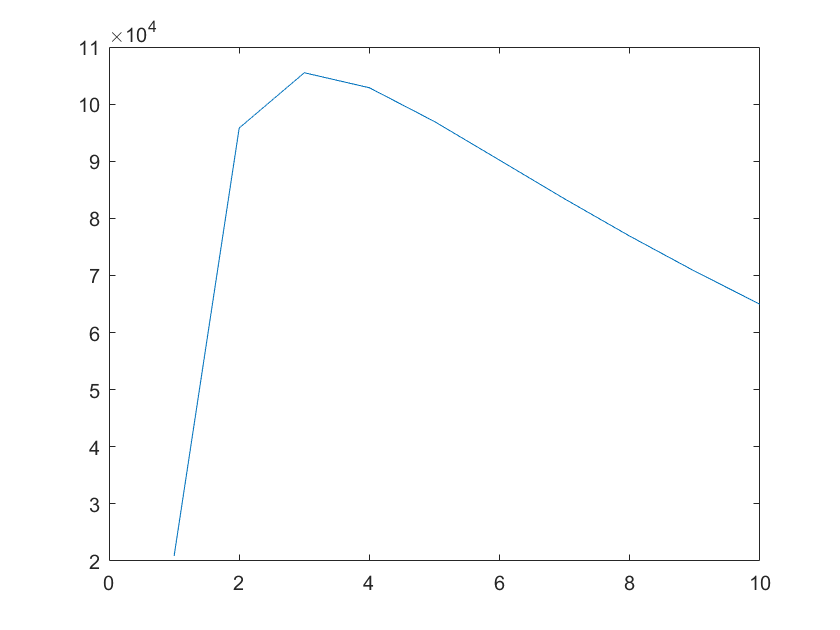

clear;
regeneration_cost = 800; % [$]
feed_rate = 70; % [kg/day]
feed_cost = 5.50; % [$/kg]
operation_cost = 300; %[$/day]
fixed_general_overhead_cost = 100000; % [$/year]
yield_day1 = 0.87;
product_value = 31; % [$/kg]
year = 300; % [days]

total_feed = feed_rate * year;
days = [1:1:300];
yield_eff = yield_day1 ./ (days .^ 0.25);

yield = zeros(300,1); 
profit = yield;
for i = 1:year
    j = 1;
    feeds = 0;
    while j <= i
        feeds = feeds + (total_feed * yield_eff(j));
        j = j + 1;
    end
    yield(i) = feeds / i;
    cost = (regeneration_cost * year / i) + (feed_cost * total_feed) + (operation_cost * year) + fixed_general_overhead_cost;
    revenue = yield(i) * product_value;
    profit(i) = revenue - cost;
end
 
plot(days, profit)
xlim([0,10])

The plot shows that the maximum profit is at 3 days. 

profit(3)

ans = 1.0549e+05

**The maximum profit is $105490 per year. **

## Problem 1 (Blackboard):

You have asked to design minimum annualized cost regenerative heat exchanger for Peoples Brewing Co. to partially cool 100 gal/min of 200F wort by heating 75 gal/min 50F water  to be used in the mash tun.    Please select a heat exchanger type and determine the heat exchanger area that will minimize the annualized cost.   Plot area vs Q  and annualized cost vs  area.

Cost of cooling the wort is $15/10^6 BTU

Cost of heating the water is  $8/10^6 BTU

Cost of money  15% (min acceptable rate of return)

Equipment life    10yrs    straight line depreciation  

Salvage value 10%

Income tax rate  25%

Capital Gains tax rate 20%

Pressure  drop   5 psi

Assume the properties of water for the wort.

clear;
mass_wort = 100; % gal/min
T_wort = 200; % F
mass_water = 75; % gal/min
T_water = 50; % F
cooling_wort_cost = 15/10e6 / 1.05506; % $/kJ
heating_water_cost = 8/10e6 / 1.05506; % $/kJ
cost_money = 0.15; % minimal acceptable rate of return
life = 10; % years, straight line depreciation
salvage = 0.1; % fraction of initial value
tax_income = 0.25; % income tax rate
tax_capital_gains = 0.2; % capital gains tax rate
delta_p = 5; % psi
cp = 4.19; % kJ/kg.K 
U = 340; % W/m^2.K


$$\begin{array}{l}
Q_2 =m_2 c_{\mathrm{p2}} \left(200-T_2 \right)\\
Q_1 =m_1 c_{\mathrm{p1}} \left(T_1 -50\right)\\
Q_1 =Q_2 =Q\\
Q=\mathrm{UA}\left(\frac{200-T_1 +\Delta T_2 -50}{2}\right)\\
Q=\mathrm{UA}\left(\frac{75+T_2 -T_1 }{2}\right)\\
T_2 =200-\frac{m_1 c_{\mathrm{p1}} }{m_2 c_{\mathrm{p2}} }\left(T_1 -50\right)
\end{array}$$


Assuming the wort has the same properties as the water, cp1 = cp2


$$\begin{array}{l}
T_2 =200-\frac{m_1 }{m_2 }\left(T_1 -50\right)\\
m_1 c_{\mathrm{p1}} \left(T_1 -50\right)=\mathrm{UA}\left(200-T_1 +150-\frac{m_1 }{m_2 }\left(T_1 -50\right)\right)
\end{array}$$


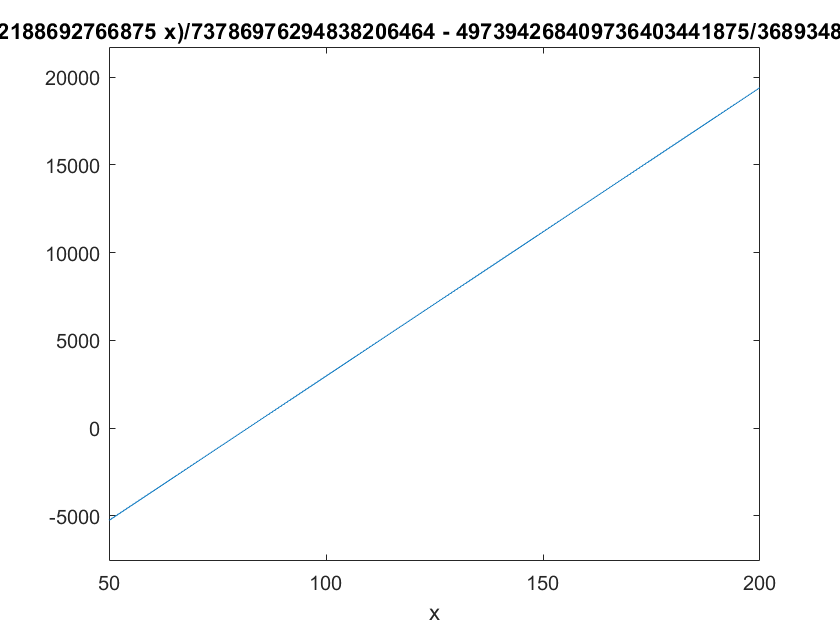

syms x % T1
Q = mass_water * cp * (((x - 50) - 32) * 5 / 9);
A = Q / (U * (((200 - x) - 32 * 5 / 9) + ((150 - 32) * 5 / 9) - mass_water / mass_wort * ((x - 50) - 32) * 5 / 9));

cost = Q * (cooling_wort_cost + heating_water_cost) * 60 * 300 * 24; % cost per year


ezplot(cost, [50,200])

If a cost of a heat exchanger and the value of the product were given, I would annualize that cost and find the depreciation and find the taxes. I would then plot the total cost with respect to the area of the heat exchanger and find the minimum on the graph. 

## Problem 2 (Blackboard): 

Design a minimum annualized cost for a low shear sanitary pumping system to deliver 20kg/s of a pseudoplastic biological fluid of a density of 1040kg/m3  n’=0.40   K’= 15 Ns^n’/m2  from one tank to another tank maintaining the same height 150 meters away.   plot delta P vs dia and annualized cost vs dia.

Derive an analytical solution

Min acceptable incremental rate of return   = 20%

Equipment life 10yrs  straight line depreciation   

Income Tax rate 30%

Capital Gains Tax  20%

Inflation 5%

Salvage value 10% of initial cost

Electricity cost $0.10/kwh

clear; 
mass = 20; % kg/s
rho = 1040; % kg/m^3
n_prime = 0.40;
k_prime = 15; % Ns^n'/m^2
distance = 150; % m
return_rate = 0.2; % minimal acceptable incremental rate of return
life = 10; % years, straight line depreciation
tax_income = 0.3; % income tax rate
tax_capital_gains = 0.2; % captial gains tax rate
inflation = 0.05; 
salvage = 0.1; % value of initial cost
electricity_cost = 0.1; % $/kwh

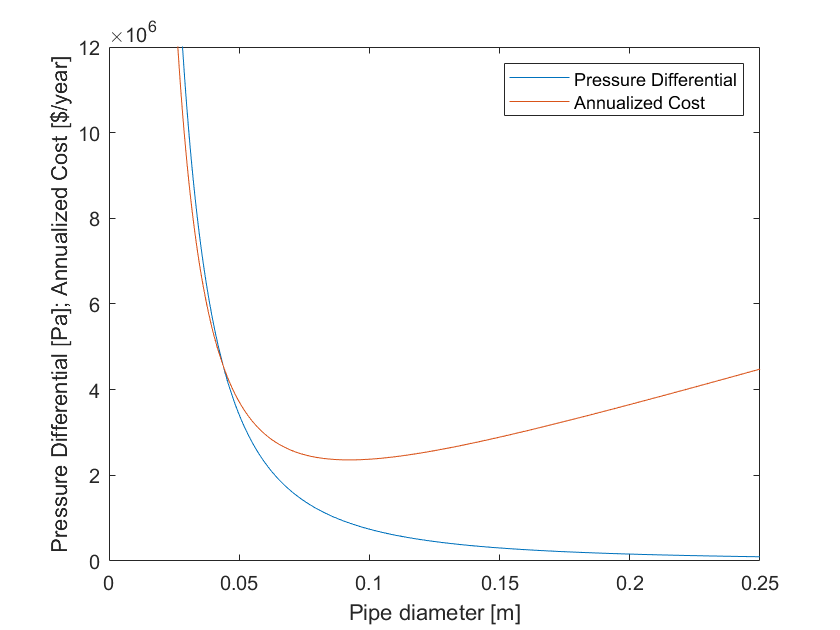

syms x % pipe diameter
area = pi * (x / 2) ^ 2; 
v = mass / rho / area; 
N_re_gen = x ^ n_prime * v ^ (2 - n_prime) * rho / (k_prime * 8 ^ (n_prime - 1));
f = 16 / N_re_gen;
delta_P = 4 * f * rho * distance / x * v ^ 2 / 2; 
q = mass / rho * 3600; 
power = q * delta_P / 600; 
t_operation = 300 * 24; % yearly hours, assuming 300 days of working per year
A_electricity = power * electricity_cost * t_operation / 100; 
PP = 100000; % [$ per unit volume of pipe], assumed as none was given
pipe_cost_install = PP * x * distance; 
depreciation = pipe_cost_install - single_future(salvage * pipe_cost_install, return_rate, life) / life;
A_fixed = present_annual(pipe_cost_install, return_rate, life) - future_annual(salvage * pipe_cost_install, return_rate, life) + depreciation;
A_total = A_fixed + A_electricity; 
ezplot(delta_P, [0, 0.25])
hold on
ezplot(A_total, [0, 0.25])
hold off
ylim([0, 12e6])
ylabel('Pressure Differential [Pa]; Annualized Cost [$/year]')
xlabel('Pipe diameter [m]')
legend('Pressure Differential', 'Annualized Cost')
title(' ')

opt_diam = newton_raphson(A_total, 0.05, 0.001)

opt_diam = 0.0401 + 0.0599i

**Answer: The optimum diameter is 0.0401 m.**

## Problem 3 (Blackboard): Katie

Develop an algorithm to determine the minimum annualized cost of the unit operation you are designing for your capstone project.    

Discuss:

Objective function to minimize annualized cost.

Define system boundaries

Identify Primary search variable

Identify Available/set variables

Identify system Contraints 

Formulate Equations to determine equipment size as function of the primary operating variable. i.e. heat loss vs insulation thickness,  power required vs pipe diameter.  


$$C_{\mathrm{annual}\;} =C_{\mathrm{fixed}} +C_{\mathrm{variable}}$$



$$\begin{array}{l}
{\;\;\;\;\;\;\;\;C}_{\textrm{fixed}} =\textrm{annualized}\left(C_{\textrm{equipment}+\textrm{installation}} \right)+C_{\textrm{maintenance}} +C_{\textrm{depreciation}} \\
{\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;C}_{\textrm{maintenance}} =0\ldotp 15\left(C_{\textrm{equipment}+\textrm{installation}} \right)\\
{\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;C}_{\textrm{depreciation}} =\frac{\left(C_{\textrm{equipment}+\textrm{installation}} -P_{\textrm{salvage}} \right)}{n}\\
{\;\;\;\;\;\;\;\;C}_{\textrm{variable}} =C_{\textrm{energy}} +C_{\textrm{labor}} \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;C_{\textrm{energy}} =\left(P_{\textrm{pump}} +P_{\textrm{atomizer}} +P_{\textrm{heat}\;\textrm{exchanger}} \right)*c_{\textrm{electricity}} \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;P_{\textrm{pump}} =\frac{q_{\textrm{yogurt}} \textrm{gh}}{3600000}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;P_{\textrm{atomizer}} =0\ldotp 0000000102*q_{\textrm{yogurt}} *{\left(N*d_{\textrm{atomizer}} \right)}^2 \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;d_{\textrm{atomizer}} =0\ldotp 13\;d_{\textrm{dryer}} \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;P_{\textrm{heat}\;\textrm{exchanger}} =q_{\textrm{air}} c_{p,\textrm{air}} \left(T_f -T_i \right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;h_{\mathrm{dryer}} =\left(\frac{q_{\mathrm{air}} }{\rho_{\mathrm{air}} }+\frac{q_{\textrm{yogurt}} }{\rho_{\mathrm{yogurt}} }\right)\left({\pi \left(\frac{d_{\mathrm{dryer}} }{2}\right)}^2 \right)t_{\mathrm{residence}} \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;q_{\textrm{air}} =0\ldotp 99\left(\frac{q_{\mathrm{air}} }{\rho_{\mathrm{air}} }+\frac{q_{\textrm{yogurt}} }{\rho_{\mathrm{yogurt}} }\right)\rho_{\mathrm{air}} \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;t_{\textrm{residence}} =\frac{\lambda_w \rho x_w D_p^2 }{12k_f \left(T_f -T_{\textrm{yogurt}} \right)}\\
{\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;C}_{\textrm{labor}} =t_{\textrm{operation}} *C_{\textrm{hourly}\;\textrm{wage}} \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;t_{\textrm{operation}} =\frac{r_{\textrm{production},\textrm{annual}} }{q_{\textrm{yogurt}} \left(1-x_w \right)}
\end{array}$$


The primary search variable is the mass flow rate of yogurt (q_yogurt). 

Available/set variables include

- Annual costs, C_annual (dependent upon fixed and variable annual costs)

- Fixed annual costs, C_fixed (dependent upon the annualized cost of the installed equipment, the annual maintenance costs, and depreciation)

- Equipment costs, C_equipment+installation (a function of the size of the equipment)

- Maintenance costs, C_maintenance (dependent upon the equipment costs)

- Depreciation, C_depreciation (dependent upon the cost of the equipment, the salvage value of the equipment, and the life of the equipment)

- Salvage value, P_salvage (set, range $0 - 10% of initial cost)

- Life of equipment, n (set, range 5-15 years)

- Variable annual costs, C_variable (dependent upon energy costs and labor costs)

- Energy costs, C_energy (dependent upon the power requirements of the pump, the atomizer, and the air heater and the cost of electricity)

- Pump power, P_pump (dependent upon the mass flow rate of yogurt, the height change required, and gravity)

- Height change, h (set, range 0 - height of dryer)

- Gravity, g (constant)

- Atomizer power, P_atomizer (dependent upon the mass flow rate of the yogurt, rotational speed of the centrifugal atomizer disk, and the diameter of the disk)

- Rotational speed of centrifugal atomizer disk, N (set, range 4000-65000 rpm)

- Diameter of disk, d_atomizer (dependent upon the diameter of the dryer)

- Dryer Diameter, d_dryer (set, 1 - 10 m)

- Power of the heat exchanger, P_heat exchanger (dependent upon the mass flow rate of air, the specific heat of air, and the final and initial temperatures of the air)

- Specific heat of air, c_p air (constant)

- Final temperature of air, T_f (set, range 100 - 200 C)

- Initial temperature of air, T_i (set, range 20-30 C)

- Height of heat exchanger (dependent upon the mass flow rates and densities of the yogurt and air, the diameter of the dryer, and the residence time)

- Mass flow rate of air, q_air (dependent upon the yogurt mass flow rate and the densities of the yogurt and air)

- Density of yogurt, rho_yogurt (set)

- Density of air, rho_air (constant)

- Residence time, t_residence (dependent upon the latent heat of vaporization of water, the density of yogurt, the water content of the initial yogurt, the droplet size, the heat transfer coefficient of the yogurt and film, and the temperature of the air and the yogurt) 

- Latent heat of vaporization of water, lambda_w (constant)

- Water content of yogurt, x_w (set, range 0.75-0.9)

- Droplet size, D_p (set, range 70-100 microns)

- Heat transfer coefficient of yogurt and film, K_f (constant)

- Temperature of yogurt, T_yogurt (set, range 20-30 C)

- Cost of labor, C_labor (dependent upon yearly operation time and hourly wage)

- Yearly operation time, T_operation (dependent upon annual rate of production, mass flow rate of yogurt, and the water content of the yogurt)

- Annual rate of production, r_production annual (determined by target market, range 1000 - 68000 kg)

- Hourly wage, C_wage (set, range 8.25-20 $/hr)

The system constraints and boundaries are listed as variable ranges. 

## Functions

function x_root = newton_raphson(f, x1, error_tol)
    x      = x1;
    zero   = double(subs(f));                                  % sets zero to the value of the 
                                                                   % function at the given x 
                                                                   % point
    x_root = x1;                                               % renames input x value
    while abs(zero) > error_tol                                % checks to see if another 
                                                                   % iteration should be 
                                                                   % performed
        x     = x_root;
        slope = double(subs(diff(f)));                         % finds the slope of the function 
                                                                   % at the given point
        if slope == 0                                          % checks for a minimum or maximum
            fprintf('Error: stuck at minimum or maximum of function.\n')
            zero   = 0;                                        % breaks the while loop so that the 
                                                                   % function doesn't go on forever
            x_root = 'N/A'; 
        else
            b      = zero - slope * x_root;                    % finds the b of the function 
                                                                   % y = mx + b
            x_root = double(-b / slope);                       % finds the new x where y = 0 for 
                                                                   % the linear function
            x      = x_root;
            zero   = double(subs(f));                          % finds the value of the function 
                                                                   % at the x found above
        end
    end
    if x_root == 'N/A'                                         % changes the zero value to N/A in 
                                                                   % the case that a maximum was 
                                                                   % found after loop break
        zero  = 'N/A';
    end
end

function A = present_annual(P, i, N)
    % capital recovery
    A = P * (i * (1 + i) ^ N) / (((1 + i) ^ N) - 1);
end

function A = future_annual(F, i, N)
    % sinking fund
    A = F * i / ((1 + i) ^ N - 1);
end

function F = single_future(P, i, N)
    % single payment compount amount
    F = P * (1 + i) ^ N;
end